Canny ridge filter testing

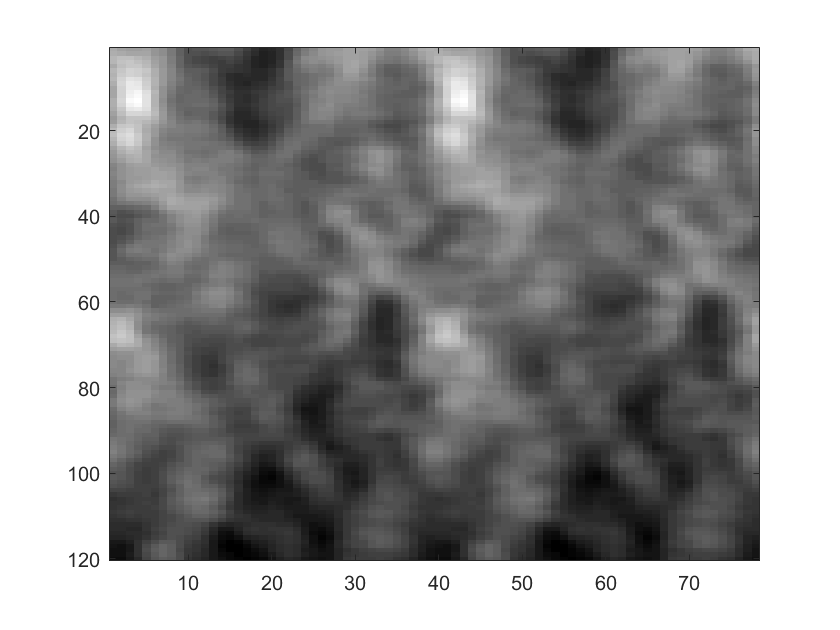

fname1 = '..\testing\testKymographs\SM1_JF-549_500ms.exp_50.Power_100x6s_3_MMStack_Pos0.ome_denoise_reg_ring15_kymoWrap.tif';
fname2 = '..\testing\testKymographs\180327_Sam1_1mW_RingHiLO_1_MMStack_Pos0.ome_denoise_reg_ring1_kymoWrap.tif';

im = imread(fname2);
im(end,:)=[];%remove the last black (non-data) row
imagesc(im);
colormap gray

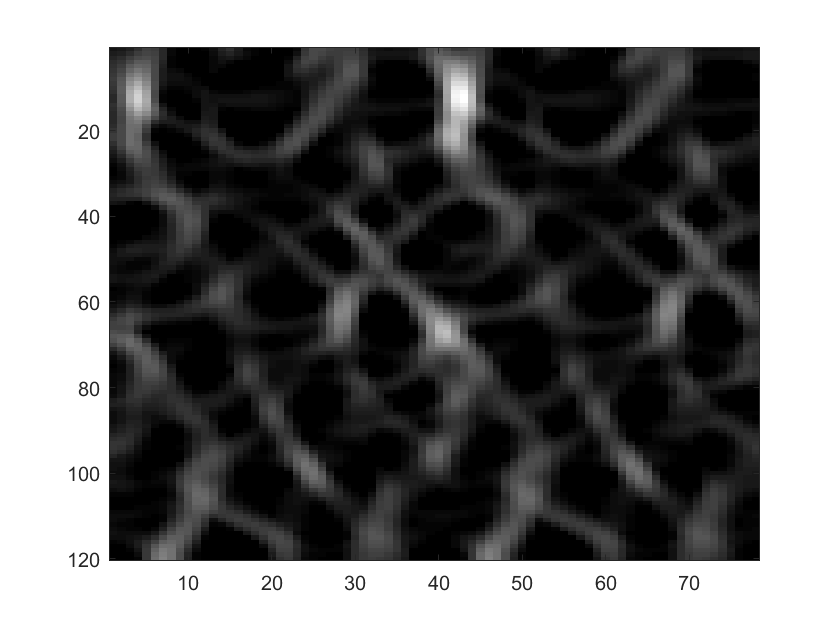


blurSigma = 2;
[ridgeBW ridge ridge_nms ] = cannyridgefilter(im,'BlurSigma',blurSigma,'NMS-con','4-con');
imagesc(ridge);
colormap gray;

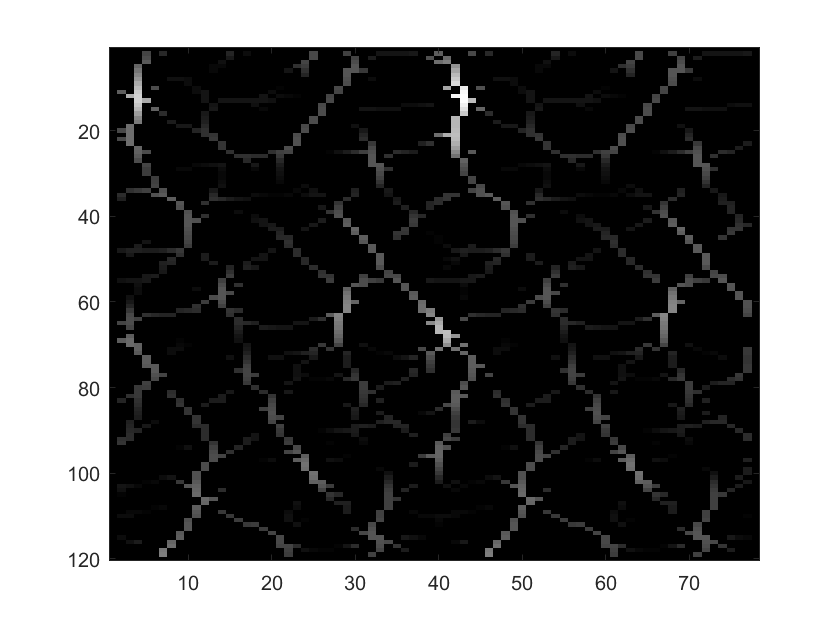

imagesc(ridge_nms);
colormap gray;

looks pretty good

What if we try 45 degrees too?

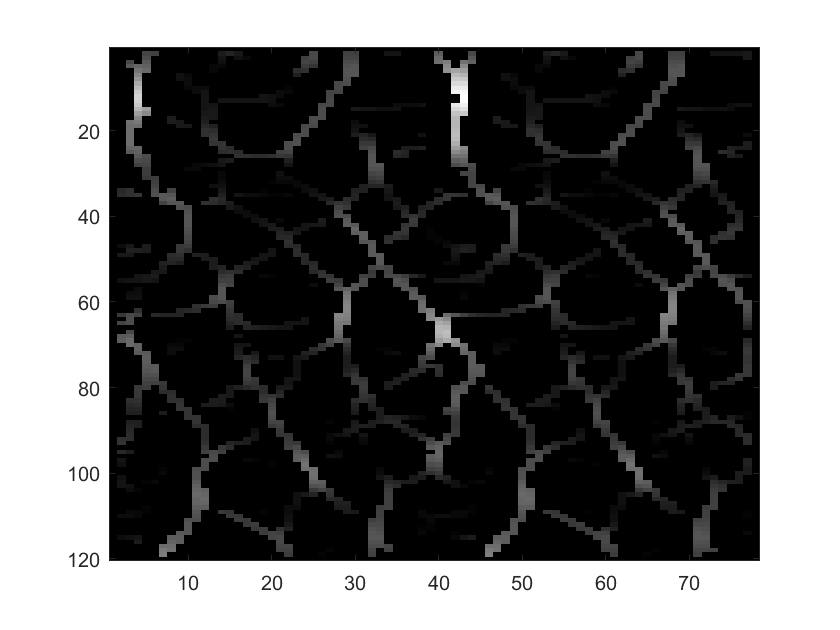

[ridgeBW ridge ridge_nms_8con ] = cannyridgefilter(im,'BlurSigma',blurSigma,'NMS-con','8-con');
imagesc(ridge_nms_8con);
colormap gray;

Ridge BW has the hysteresis applied too:

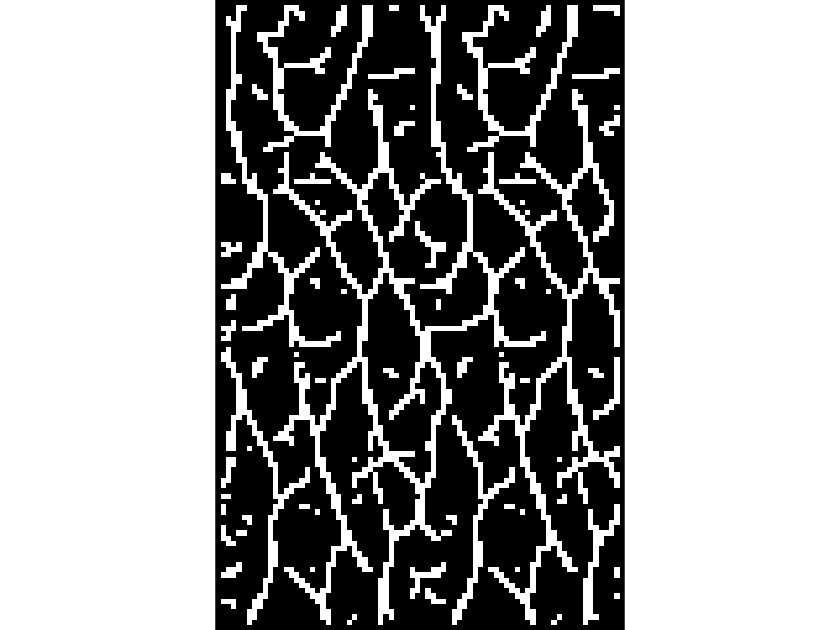

imshow(ridgeBW)

Looks good

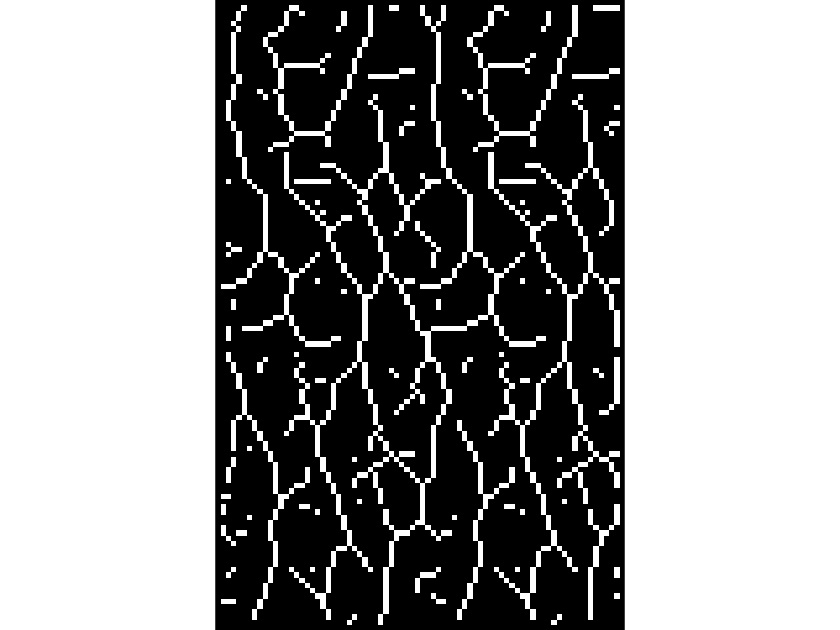

imshow(bwskel(ridgeBW))

%what if we just do horizontal NMS makes the most sense for kymogrpahs

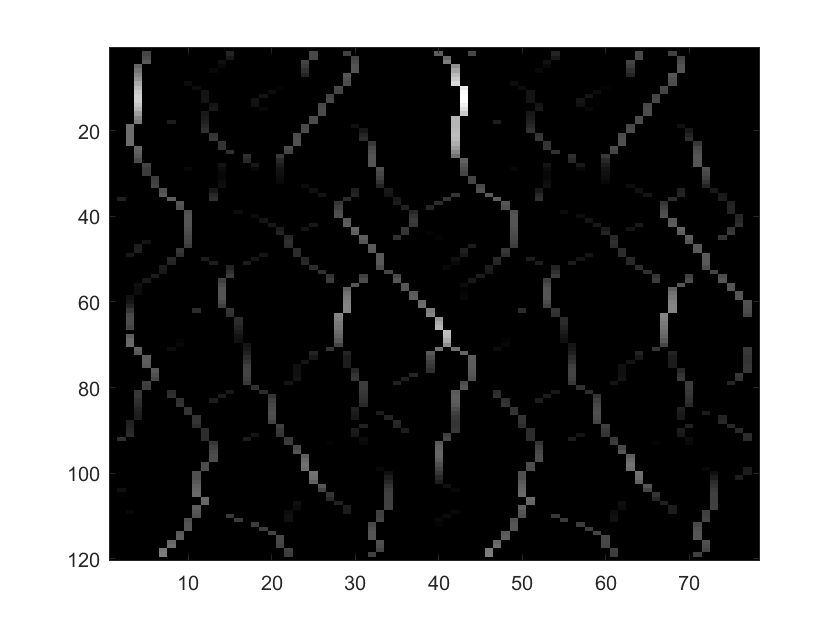

[ridgeBW ridge ridge_nms_horz ] = cannyridgefilter(im,'BlurSigma',blurSigma,'NMS-con','horz');
imagesc(ridge_nms_horz);

just horizontal connectivity but with hysteresis applied:

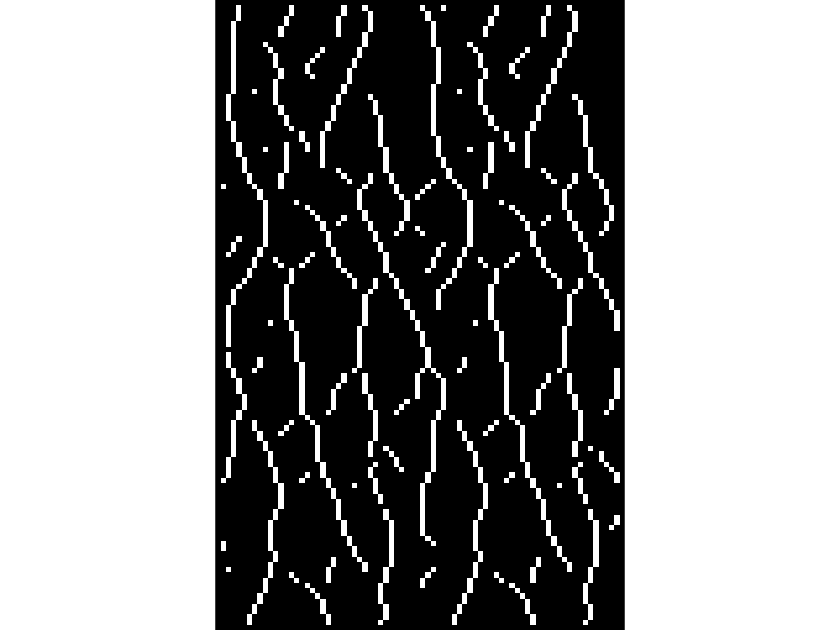

imshow(ridgeBW)

This might be a bit harsh compared to the 4-con NMS. Depends on the tracking method in the end.

What about horz connectivity with hough transform?

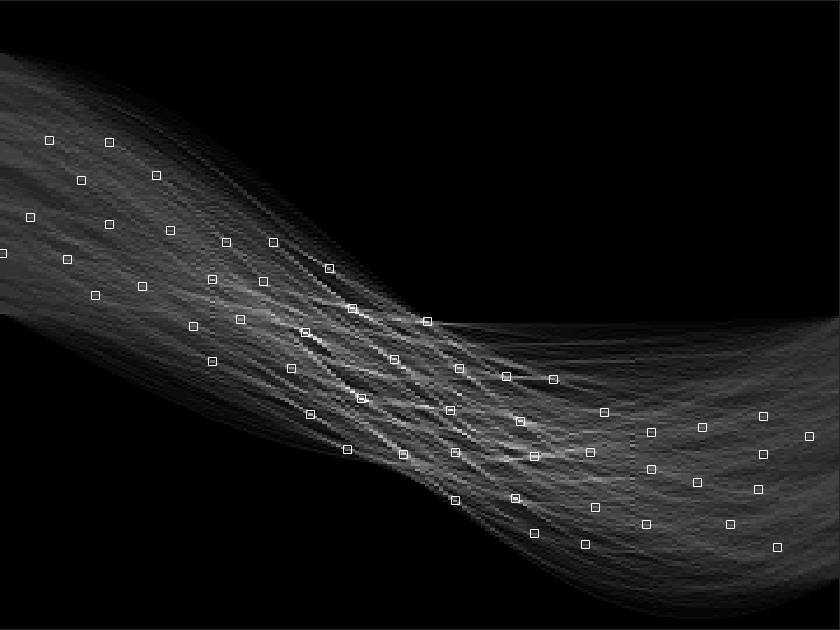

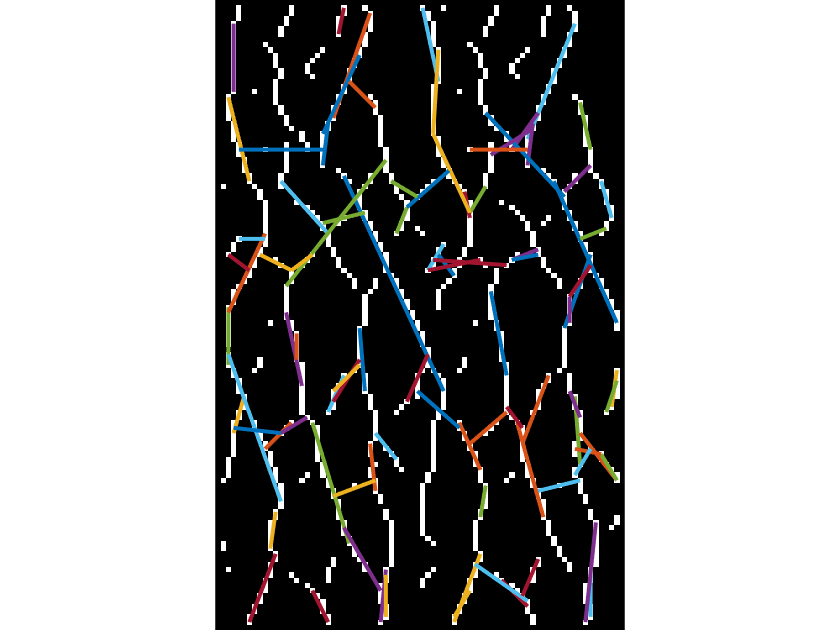

supressNHood = [21 11];%rho theta
suppressNHood = size(H)/10; %rho theta
thresh=0.3;
fillgap=5;
minlen=5;
houghline(ridgeBW,suppressNHood,thresh,fillgap,minlen)

horz canny ridge with lower th> - no look at the nms image it's basically the same